# Lab Assignements #1

### **1 Getting started**

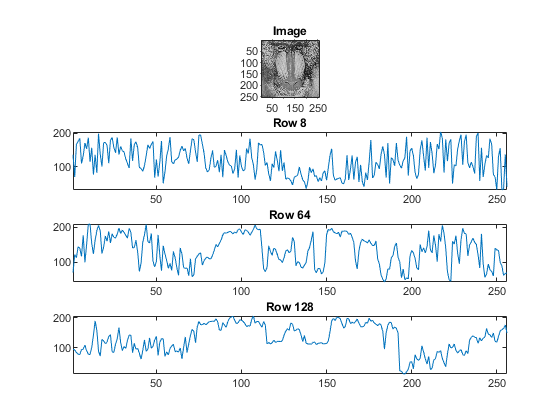

clear all; close all; clc;

addpath('extra_test_images')
addpath('standard_test_images')
addpath('crocodile')

% load color image and display it
I = imread('mandrill.tif');
% convert it to an intensity image (gray scale)
I = rgb2gray(I);
% take some image rows: 8, 64, and 128
row8 = I(8,:); row64 = I(64,:); row128 = I(128,:);
% plot something
figure;
subplot(4, 1, 1); imshow(I); title('Image'); axis image tight on;
subplot(4, 1, 2); plot(row8); title('Row 8'); axis tight;
subplot(4, 1, 3); plot(row64); title('Row 64'); axis tight;
subplot(4, 1, 4); plot(row128); title('Row 128'); axis tight;

### **2 Image Sampling**

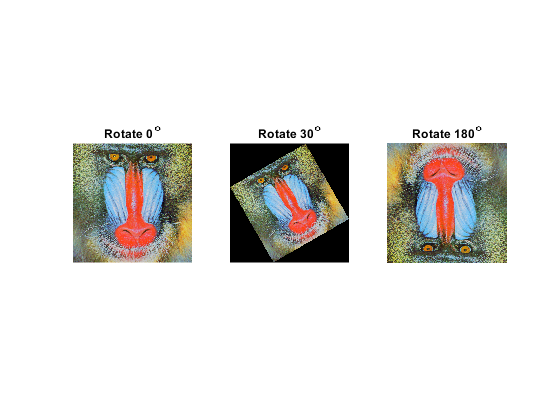

clear all; close all; clc;
I = imread('mandrill.tif');

%display 30◦ and 180◦ rotation
figure;
subplot(1, 3, 1); imshow(I); title('Rotate 0^◦');
I30 = imrotate(I, 30);
subplot(1, 3, 2); imshow(I30); title('Rotate 30^◦');
I180 = imrotate(I, 180);
subplot(1, 3, 3); imshow(I180); title('Rotate 180^◦');

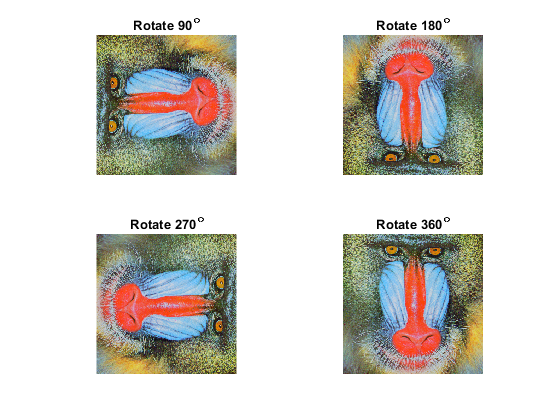


%display 90◦ rotation, 4 times in succession
figure
Irot = I;
angle = 90;
for i = 1:4
    Irot = imrotate(Irot, angle);
    subplot(2, 2, i); imshow(Irot); title(['Rotate ', num2str(i*angle) ,'^◦']);
end

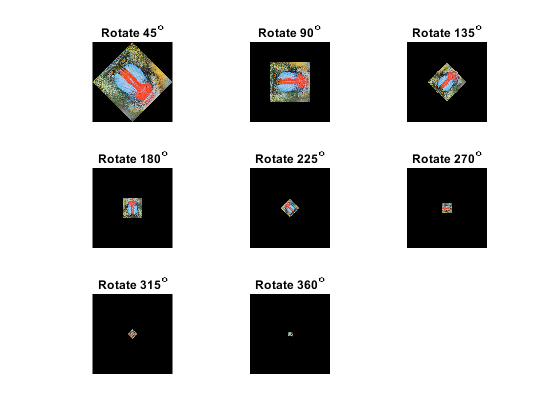


%display 45◦ rotation, 8 times in succession
figure
Irot = I;
angle = 45;
for i = 1:8
    Irot = imrotate(Irot, angle);
    subplot(3, 3, i); imshow(Irot); title(['Rotate ', num2str(i*angle) ,'^◦']);
end

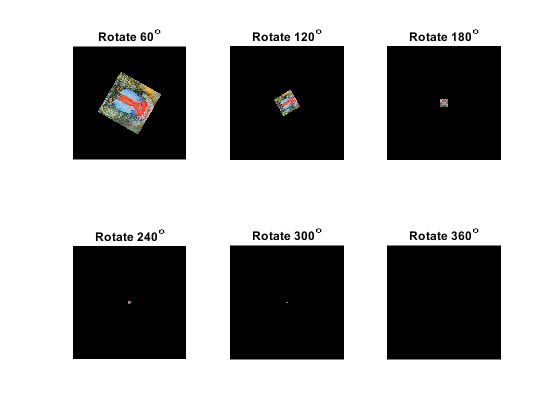


%display 10◦ rotation, 36 times in succession
figure
Irot = I;
angle = 10;
k = 1;
for i = 1:36
   %@Note: the image size increases with each iteration when rotating in succession.
    Irot = imrotate(Irot, angle); 
    if (mod(i, 6) == 0) %Display every 6th rotation only
        subplot(2, 3, k); k = k + 1;
        imshow(Irot); title(['Rotate ', num2str(i*angle) ,'^◦']);
    end
end

### **3 Grey Level Quantization**

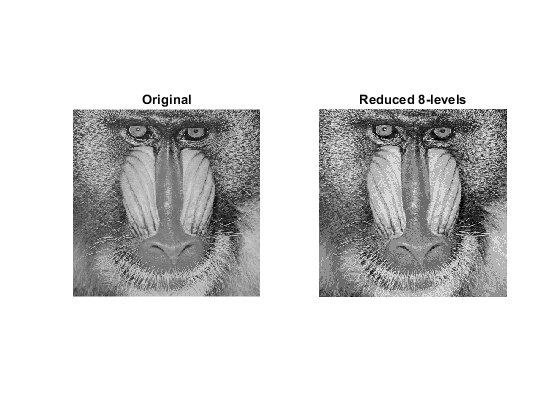

clear all; close all; clc;

I = imread('mandrill.tif'); I = rgb2gray(I);
subplot(1, 2, 1); imshow(I); title('Original');

Iout = imReduceGreyLevel(I, 8);
subplot(1, 2, 2); imshow(Iout); title('Reduced 8-levels');

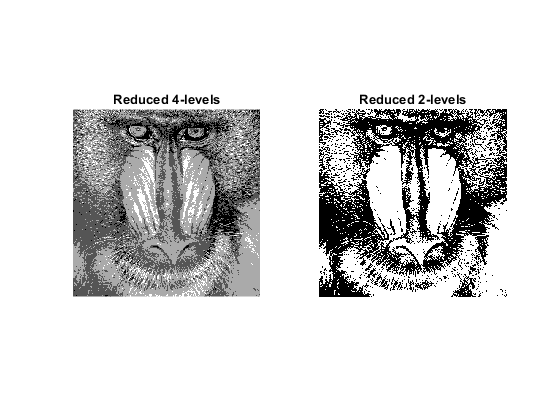


figure
Iout = imReduceGreyLevel(I, 4);
subplot(1, 2, 1); imshow(Iout); title('Reduced 4-levels');

Iout = imReduceGreyLevel(I, 2);
subplot(1, 2, 2); imshow(Iout); title('Reduced 2-levels');

### **4 Image Statistics**

### **4.1 Grey Level Images**

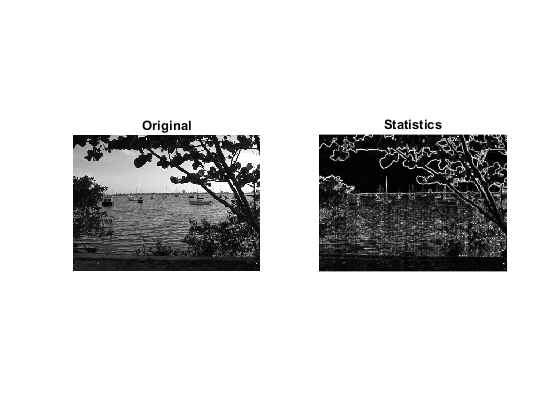

clear all; close all; clc;

I = imread('boat.tif');
figure
subplot(1, 2, 1); imshow(I); title('Original');
Istat = imGreyLevelStatistics(I);
subplot(1, 2, 2); imshow(Istat); title('Statistics');

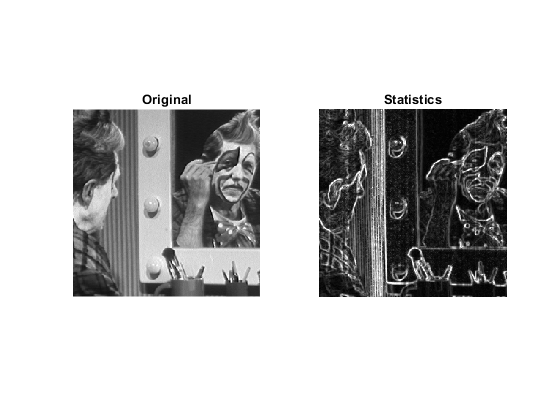


I = imread('clown.tif');
figure
subplot(1, 2, 1); imshow(I); title('Original');
Istat = imGreyLevelStatistics(I);
subplot(1, 2, 2); imshow(Istat); title('Statistics');

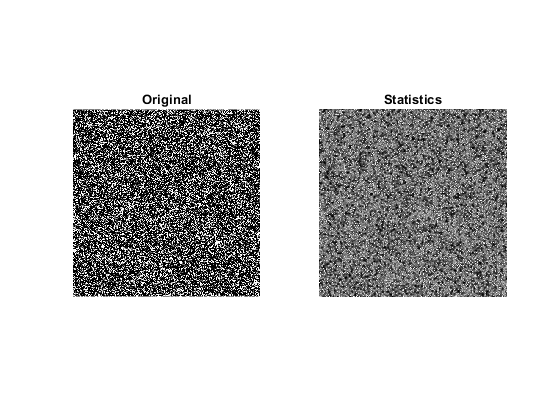


Inoise = uint8(zeros(size(I)));
Inoise = imnoise(Inoise,'gaussian', 0,1);
figure
subplot(1, 2, 1); imshow(Inoise); title('Original');
InoiseStat = imGreyLevelStatistics(Inoise);
subplot(1, 2, 2); imshow(InoiseStat); title('Statistics');

### **4.2 Image Matching using Histograms**

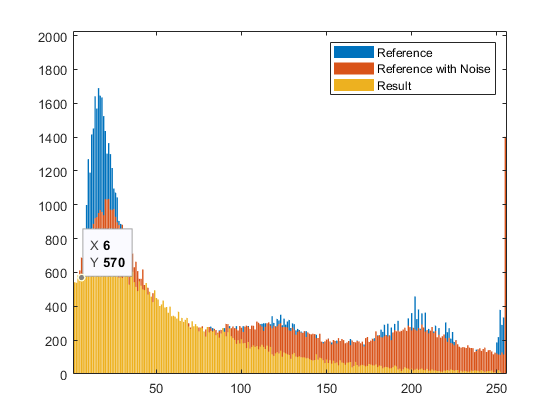

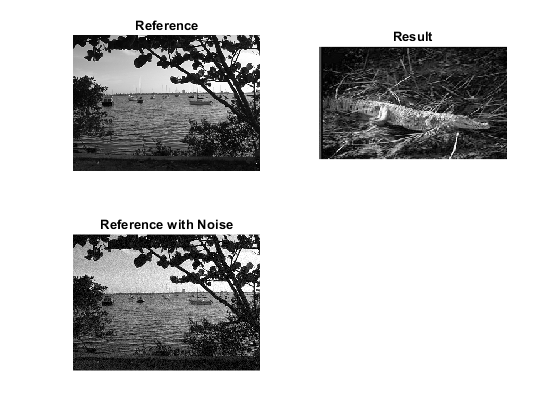

clear all; close all; clc;

%load all images in the folder
imagefiles = dir('crocodile/*.jpg'); 
numImages = length(imagefiles);

collection{numImages} = [];
for i = 1:numImages
    img = imread(imagefiles(i, 1).name);
    
    %must be grey-scale images
    img = rgb2gray(img);
    collection{i} = img;
end

%load reference image and add noise
I = imread('boat.tif');
%collection{numImages + 1} = imnoise(I,'gaussian', 0, 0.002);
collection{numImages + 1} = imnoise(I,'gaussian', 0, 0.00225489899999);

%find best match image in collection
[index, found_img] = findImage(I, collection);


%disply histogram for reference image
figure
[outHist] = imGrey2histogram(I);
bar(0:length(outHist)-1, outHist); xlim([1, length(outHist)]); hold on
ylim([0, max(outHist)*1.2])

if(index == numImages + 1)%If best match is the reference image with noise added
    
    %disply histogram for found image
    [outHist] = imGrey2histogram(found_img);
    bar(0:length(outHist)-1, outHist); xlim([1, length(outHist)]);
    legend('Reference', 'Result')
    
    %display images
    figure
    subplot(1, 2, 1); imshow(I); title('Reference');
    subplot(1, 2, 2); imshow(found_img); title('Result');
else
    
    %disply histogram for reference image with noise
    [outHist] = imGrey2histogram(collection{numImages + 1});
    bar(0:length(outHist)-1, outHist); xlim([1, length(outHist)]);
    
    %disply histogram for found image
    [outHist] = imGrey2histogram(found_img);
    bar(0:length(outHist)-1, outHist); xlim([1, length(outHist)]);
    legend('Reference', 'Reference with Noise', 'Result')
    
    %display images
    figure
    subplot(2, 2, 1); imshow(I); title('Reference');
    subplot(2, 2, 2); imshow(found_img); title('Result');
    subplot(2, 2, 3); imshow(collection{numImages + 1}); title('Reference with Noise');
end

### **4.3 Automatic Identification of Special Images**

clear all; close all; clc;

%Load all images in the folder
imagefiles = dir('crocodile/*.jpg');
numImages = length(imagefiles);    % Number of files found
for i = 1:numImages
    img = imread(imagefiles(i, 1).name);
    img = rgb2gray(img);
    collection{i} = img;
end

%Train model: calculate normal distribution of image entropy for image in collection
pd = trainImagesSpecial(collection);


%Create test set: Add "special" images to test set
images_test_set = collection;
images_test_set{numImages + 1} = imnoise(images_test_set{randi(numImages)},'gaussian', 0, 1);
images_test_set{numImages + 2} = imnoise(images_test_set{randi(numImages)},'gaussian', 0, 1);
images_test_set{numImages + 3} = imnoise(images_test_set{randi(numImages)},'gaussian', 0, 1);
images_test_set{numImages + 4} = imnoise(images_test_set{randi(numImages)},'gaussian', 0, 1);

%Find special images in test set
[special_img, special_img_entropy] = findImagesSpecial(images_test_set, pd);

**Special images**

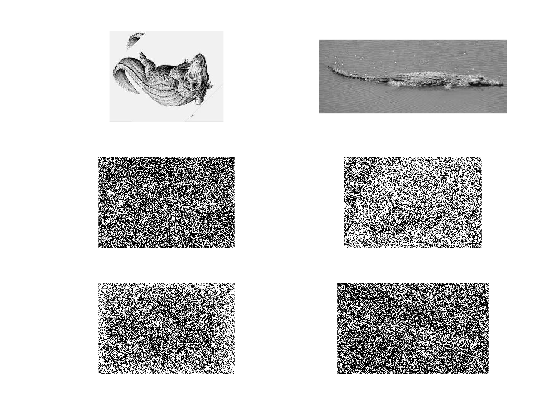

%Display "special" images in subplots
figure
factors = factor(length(special_img));
grid_width = ceil(sqrt(length(special_img)));
grid_height = grid_width;
if(length(factors) == 2)
    grid_width = factors(1);
    grid_height = factors(2);
end
for i = 1:length(special_img)
    subplot(grid_height, grid_width, i);
    imshow(images_test_set{special_img(i)});
end

**Normal distribution - image entropy**

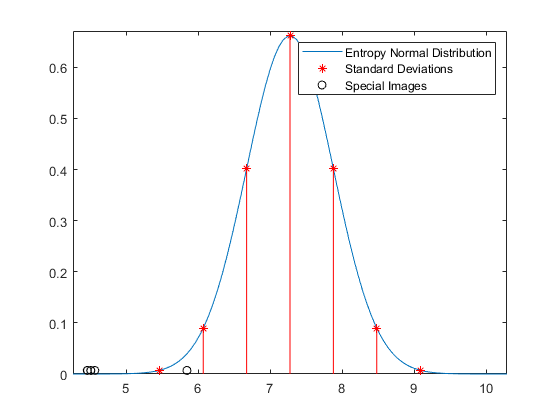

%Show normal distribution of image entropy [blue line]
figure
x_norm = linspace(pd.mu - pd.sigma * 5, pd.mu + pd.sigma * 5);
y_norm = normpdf(x_norm, pd.mu, pd.sigma);
plot(x_norm, y_norm)
hold on

%Display standard deviations [red *]
x_std = [pd.mu - pd.sigma * 3, pd.mu - pd.sigma * 2, pd.mu , pd.mu - pd.sigma * 1, pd.mu + pd.sigma * 1, pd.mu + pd.sigma * 2,  pd.mu + pd.sigma * 3];
y_std = normpdf(x_std, pd.mu, pd.sigma);
plot(x_std, y_std, '*r')

%Display position of "special" images entropy [black O]
plot(special_img_entropy, zeros(length(special_img)) + 0.007, 'Ok'); %@Note: + 0.007 to display circles better in plot

%Display standard deviation lines [red] %@Note: plotting last to make legend disply better
X = [x_std; x_std]; Y = [zeros(1, length(x_std)); y_std];
line(X, Y, 'color', 'r')
ylim([0, max(y_norm) + 0.01])
xlim([pd.mu - pd.sigma * 5, pd.mu + pd.sigma * 5])
legend('Entropy Normal Distribution', 'Standard Deviations', 'Special Images')